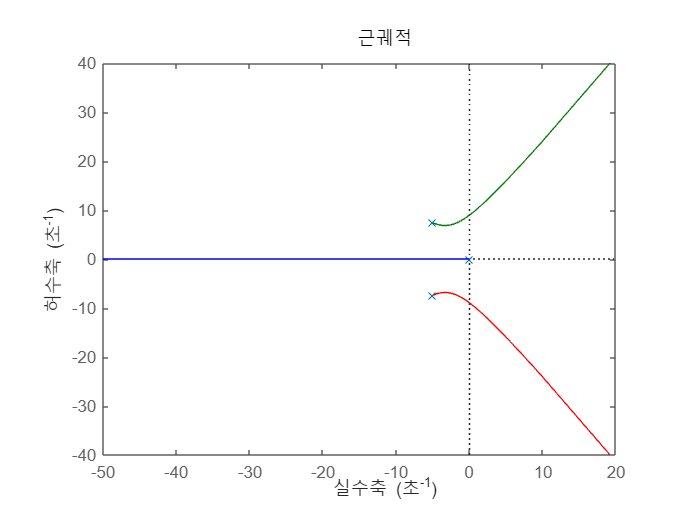

% E 7.6
clear all;

syms s K a b;
assume(K,"positive"); % 근궤적에서의 K는 양수이다.
Ls = K*(20)/(s*(s^2 + 10*s + 80));
[n, d] = numden(Ls/K);
num = sym2poly(n);
den = sym2poly(d);
sys = tf(num, den);
figure();
rlocus(sys);


G = simplify(Ls/(1 + Ls))

$$G = \frac{20\,K}{s^{3}+10\,s^{2}+80\,s+20\,K}$$


% routh_hurwitz 방식을 이용하여 시스템을 불안정하게 만드는 K값을 구한다.

[n d] = numden(G);
coef = flip(coeffs(d,s));
[M, L] = routh_hurwitz(coef);
L

$$L = \left(\begin{array}{c} 1.0\\ 10.0\\ 80.0-2.0\,K\\ \frac{40.0\,K\,\left(K-40.0\right)}{2.0\,K-80.0} \end{array}\right)$$


% routh_hurwitz 방식을 이용하여 나타낸 맨 왼쪽변의 부호가 양수만을 나타내게 하는 K값을 도출해내는 함수
eqn = L > 0;
[low, row] = size(eqn);
eqnK = 1;
for(i = 1:low)
    eqnK = eqnK&eqn(i);
end

pretty(simplify(eqnK)) 

K < 40.0 and K ~= 40.0



% routh_hurwitz 방식을 이용하여 나타낸 왼쪽변의 부호가 양수만을 나타내게 하는 K값을 도출해내는 함수

% 따라서 K값이 40보다 크거나 같을 때 시스템은 불안정해진다!!